## Parameters

clear all;
A = 5;
T = 8;
Ta = 0.15;

## Analysis

G =tf(1,[Ta 1 0])


G =
 
       1
  ------------
  0.15 s^2 + s
 
Continuous-time transfer function.
Model Properties


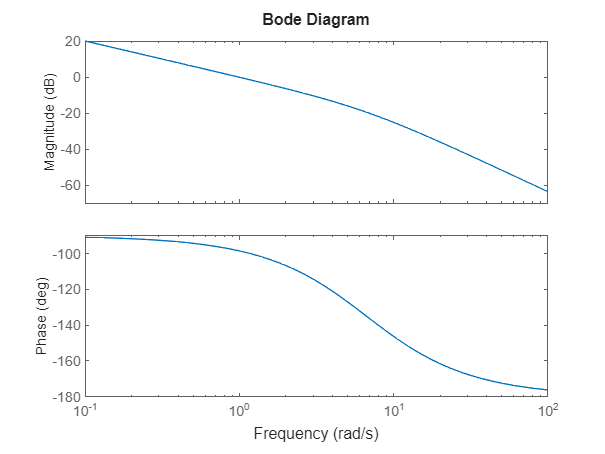

bode(G)

## Tuning

We want a settling time of around 1 sec


C0 = pidstd(1,1);

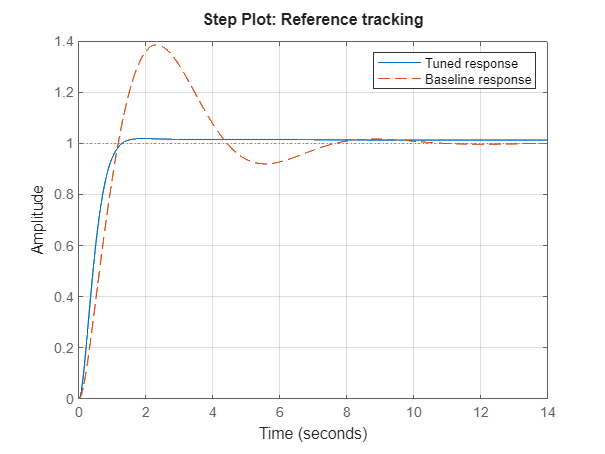

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc = 2/1;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM = 100*0.9;

% Define options for pidtune command
opts = pidtuneOptions('PhaseMargin',PM);
C02 = pidstd(1,1);

% PID tuning algorithm for linear plant model
[C,pidInfo] = pidtune(G,C02,wc,opts);

% Clear Temporary Variables
clear C02 wc PM opts

% Get desired loop response
Response_Tuned = getPIDLoopResponse(C,G,'closed-loop');
Response_Baseline = getPIDLoopResponse(C0,G,'closed-loop');

% Plot the result
f=figure();
stepplot(f,Response_Tuned,'-', Response_Baseline, '--')
legend('Tuned response', 'Baseline response');
title('Step Plot: Reference tracking')
grid on


% Display system response characteristics
disp(stepinfo(Response_Tuned))

         RiseTime: 0.7409
    TransientTime: 1.1466
     SettlingTime: 1.1466
      SettlingMin: 0.9037
      SettlingMax: 1.0182
        Overshoot: 1.8182
       Undershoot: 0
             Peak: 1.0182
         PeakTime: 1.8890




% Clear Temporary Variables
clear f Response_Tuned Response_Baseline;
C


C =
 
             1      1 
  Kp * (1 + ---- * ---)
             Ti     s 

  with Kp = 2.09, Ti = 28.6
 
Continuous-time PI controller in standard form
Model Properties


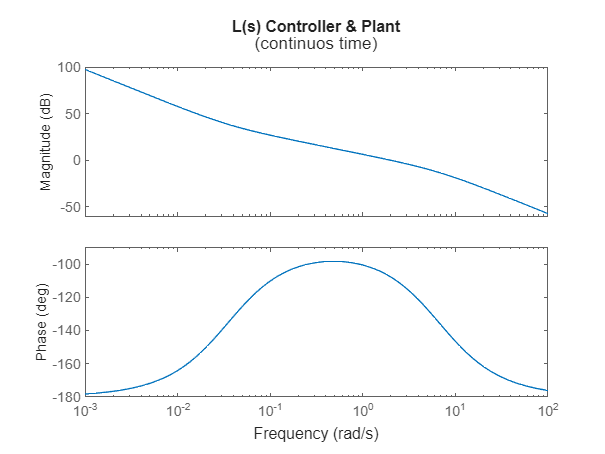


bode(G*C)
title("L(s) Controller & Plant")
subtitle("(continuos time)")

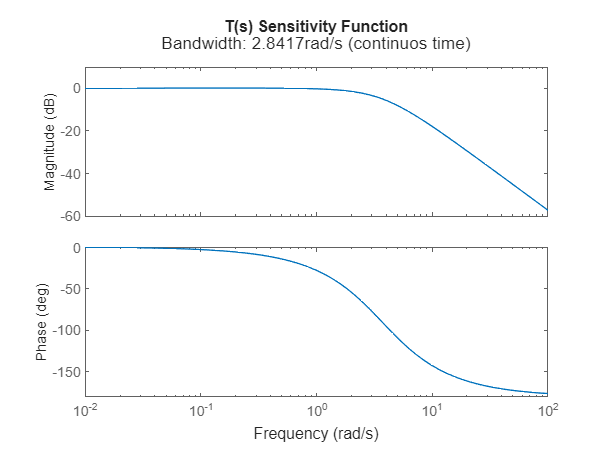


fb=feedback(G*C,1);
bode(fb)
title("T(s) Sensitivity Function")
subtitle("Bandwidth: "+bandwidth(fb)+"rad/s (continuos time)")

## SIMULINK simulation

We put a 100Hz sampling time for the time being

kp_tuner=  C.Kp;
ki_tuner = 1/C.Ti;
eta = 0.1;
simIn = Simulink.SimulationInput("tb_kinematics");
simIn = simIn.setVariable("eta_var",eta);
simIn = simIn.setVariable("openloop",0);
simIn = simIn.setVariable("kp_tuner",kp_tuner);
simIn = simIn.setVariable("ki_tuner",ki_tuner);
simIn = simIn.setVariable("Ts_s",1/100);
out = sim(simIn); %run simulation, all results returned in "out"
shape = [ out.xp_.Data'; out.yp_.Data' ];

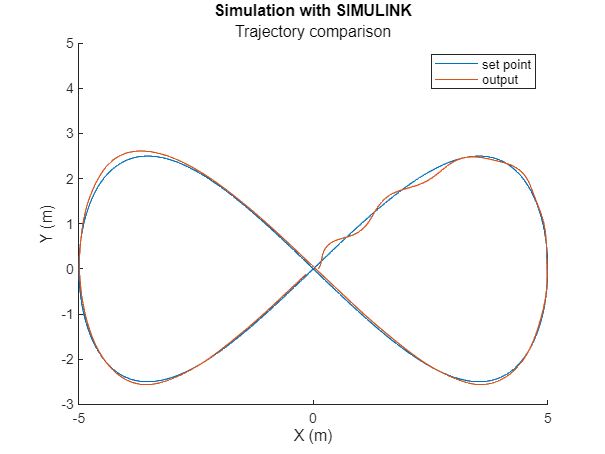


figure
hold on
plot(shape(1,:),shape(2,:))
plot(out(1,:).xp.Data,out(1,:).yp.Data)
hold off
title("Simulation with SIMULINK")
subtitle("Trajectory comparison")
legend("set point","output")
ylim([-3 5])

ylabel("Y (m)")
xlabel("X (m)")

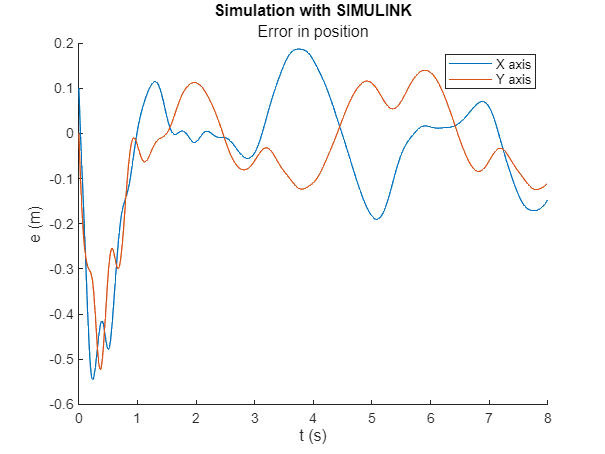


figure
hold on
plot( out(1,:).tout',out(1,:).xp.Data' -shape(1,:))
plot( out(1,:).tout',out(1,:).yp.Data' -shape(2,:))
hold off
title("Simulation with SIMULINK")
subtitle("Error in position")
legend("X axis","Y axis")
ylabel("e (m)")
xlabel("t (s)")

## Discretization

At the start we  have oscillations of around 0.25s (so with a frequency of about 4Hz) 

A candidate for the sampling time is between 10 -> 100 times this frequency.

Let's take 50x in between

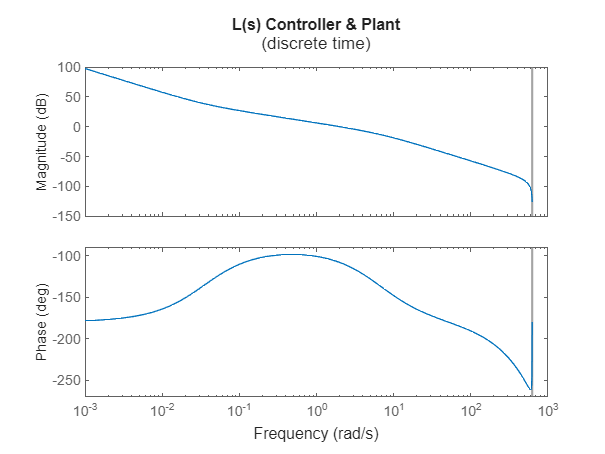

Ts_s = 1/200;
Gd = c2d(G,Ts_s);
Cd = pidstd(C.Kp,C.Ti,"Ts",Ts_s);



bode(Gd*Cd)
title("L(s) Controller & Plant")
subtitle("(discrete time)")

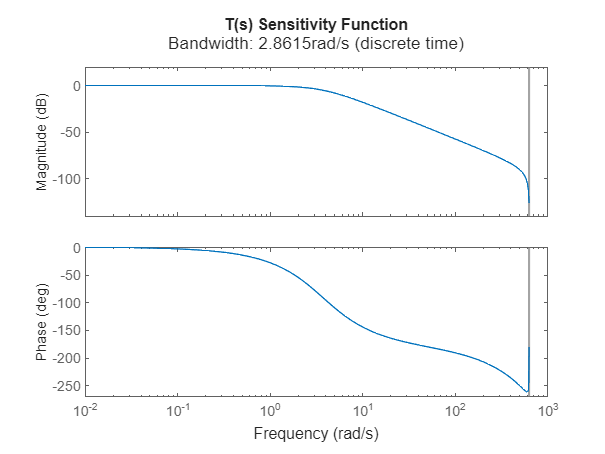


fbd=feedback(Gd*Cd,1);
bode(fbd)
title("T(s) Sensitivity Function")
subtitle("Bandwidth: "+bandwidth(fbd)+"rad/s (discrete time)")

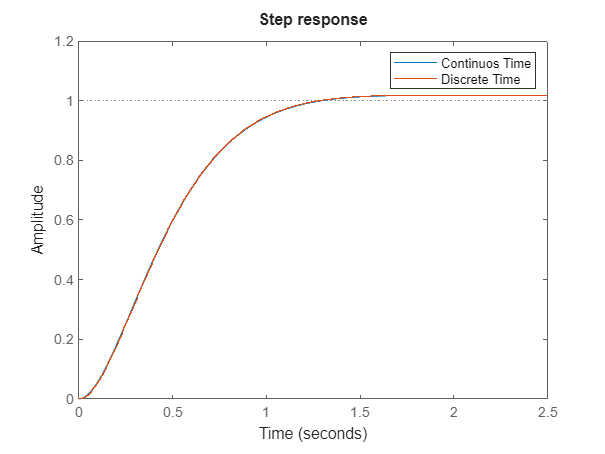


figure
hold on
step(fb)
step(fbd)
hold off
title("Step response")
legend("Continuos Time","Discrete Time")